clc;
clear all;

load("I0_reaction2.mat");

% Step 1 calculate dark Array
% PATH = "DARKFILE";
% prefix = " ";
% suffix = " ";
% dark_Array = calculateDarkMean(PATH, prefix, suffix)

% dark array
dark_Array = dark_reaction2(:, 2);

% Step 2 calculate I0_array

% Todo

% I0 array
I0_Array = I0_dark_2_I0_reaction2(:, 2);

% PATH = "I-reaction11_f000000000000_15_ascii";
% prefix = "I-reaction11_f000000000000_15_";
% suffix = ".txt";
% 
% result = calXASMean(PATH, prefix, suffix, I0_Array, dark_Array)

% 350_450mv
% Step 3 calculate I and XAS result array
PATH = "D:\J.XAS-Statics\Lin\Research_Project\solei beamtime\2018-12\2mM-FeSO4-NiSO4-20181207\350-450mv";

result_350_450 = calXASMeanMultifile(PATH, I0_Array, dark_Array);

% 450_450mv
% Step 3 calculate I and XAS result array
PATH = "D:\J.XAS-Statics\Lin\Research_Project\solei beamtime\2018-12\2mM-FeSO4-NiSO4-20181207\450_450mv\450-450mv";

result_450_450 = calXASMeanMultifile(PATH, I0_Array, dark_Array);

% 450_550mv
% Step 3 calculate I and XAS result array
PATH = "D:\J.XAS-Statics\Lin\Research_Project\solei beamtime\2018-12\2mM-FeSO4-NiSO4-20181207\450_550mv";

result_450_550 = calXASMeanMultifile(PATH, I0_Array, dark_Array);

% 450_500mv
% Step 3 calculate I and XAS result array
PATH = "D:\J.XAS-Statics\Lin\Research_Project\solei beamtime\2018-12\2mM-FeSO4-NiSO4-20181207\450-500mv";

result_450_500 = calXASMeanMultifile(PATH, I0_Array, dark_Array);

% 500-500mv
% Step 3 calculate I and XAS result array
PATH = "D:\J.XAS-Statics\Lin\Research_Project\solei beamtime\2018-12\2mM-FeSO4-NiSO4-20181207\500_500mv\500-500mv";

result_500_500 = calXASMeanMultifile(PATH, I0_Array, dark_Array);

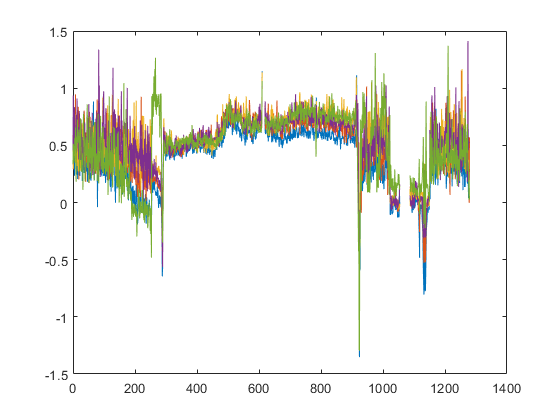

% step 4 plot;
x_axis = 0:1:length(result_350_450) -1 ;

plot(x_axis, result_350_450, ...
    x_axis, result_450_450, ...
    x_axis, result_450_550, ...
    x_axis, result_450_500, ...
    x_axis, result_500_500);

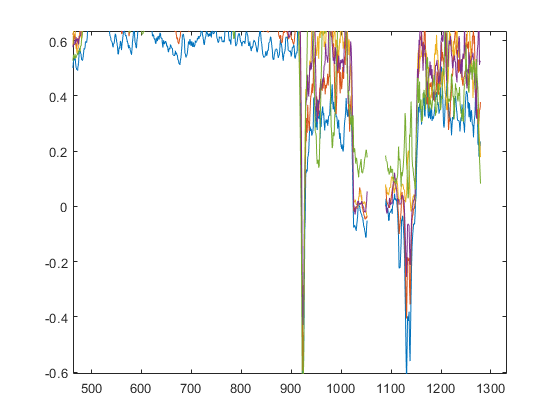

 b_350_450 =movmean(result_350_450, 5);
 b_450_450 =movmean(result_450_450, 5);
 b_450_550 =movmean(result_450_550, 5);
 b_450_500 =movmean(result_450_500, 5);
 b_500_500 =movmean(result_500_500, 5);
 plot(x_axis, b_350_450,...
     x_axis, b_450_450, ...
     x_axis, b_450_550, ...
     x_axis,b_450_500, ...
     x_axis,b_500_500);

% Fe2O3_averagedResult = movmean(Fe2O3_result, 5);
% Fefoil_averagedResult = movmean(Fefoil_result, 5);
% FeO_averagedResult = movmean(FeO_result, 5);

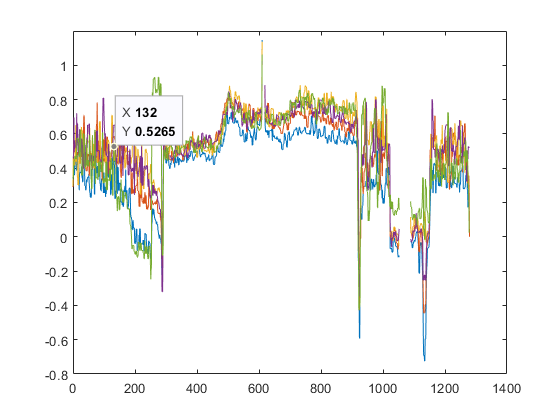

 m_350_450 =medfilt1(result_350_450, 5);
 m_450_450 =medfilt1(result_450_450, 5);
 m_450_550 =medfilt1(result_450_550, 5);
 m_450_500 =medfilt1(result_450_500, 5);
 m_500_500 =medfilt1(result_500_500, 5);
 plot(x_axis, smoothdata(m_350_450),...
     x_axis, m_450_450, ...
     x_axis, m_450_550, ...
     x_axis,m_450_500, ...
     x_axis,m_500_500);